# WEEK 2 NUMERICAL INTEGRATION

You may use the code below to help you solve tasks 2 and 3.

Note: replace "FILL_IN_HERE" with your own code (numbers and/or equations) for the code to work

clear
clc

%%% Setup. The following variables will be used throughout the code

m = 75; %mass of the box or skydiver (kg)
C1 = 8; %coefficient of drag force
C2 = 60; %coefficient of lift force
v0 = [44.7, 0]; %velocity vector in x and y (m/s)
g = -9.81; %gravitational acceleration (m/s^2)
y0 = 2500; %Initial elevation (m)
x0 = 0; %Initial horizontal position (m)

dt = 0.01; %Numerical integration step size

t = 0:dt:150  %Time array

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


# Task 2: Numerical methods

Use the incomplete code below to solve task 2.

vx(1) = v0(1); %Initial x velocity
vy(1) = v0(2); %Initial y velocity

x(1) = x0; %Initial x position
y(1) = y0; %Initial y position

for i=1:length(t)-1
    vy(i+1) = vy(i)+g*dt; %Velocity in the y direction in the next time step
    vx(i+1) = vx(i); %Velocity in the x direction in the next time step
    x(i+1) = x(i)+vx(i)*dt; %Position in the x direction in the next time step
    y(i+1) = y(i)+vy(i)*dt+0.5*g*(dt^2); %%Position in the y direction in the next time step
    if y(i+1) <= 0
        y(i+1) = 0; %Limits the system so that, if the computed position is <0
                    %it forces it back to 0.
        vy(i+1) = 0;
    end
end
figure(1)

[vymin, tg] = min(vy)

vymin = -221.4117

tg = 2258

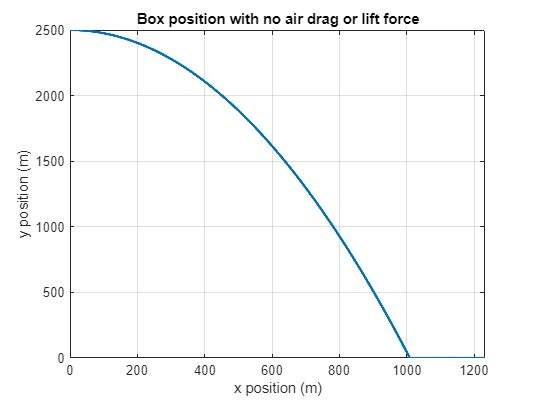


plot(x,y, LineWidth=2) %plot trajectory of falling y vs x
xlim([0,x(tg+500)])
xlabel 'x position (m)'
ylabel 'y position (m)'
title 'Box position with no air drag or lift force'
grid on

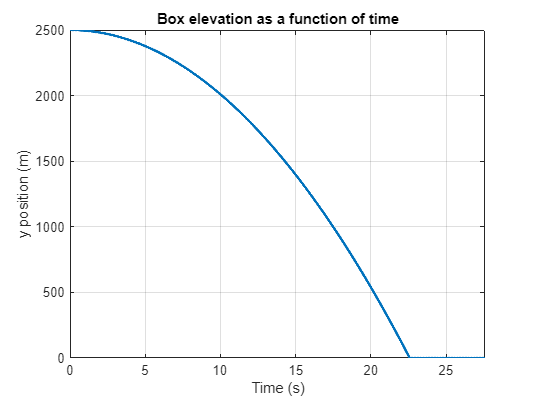


figure(2)
plot(t,y, LineWidth=2) %plot the elevation of the box as a function of time
xlim([0,t(tg+1)+5])
xlabel 'Time (s)'
ylabel 'y position (m)'
title 'Box elevation as a function of time'
grid on

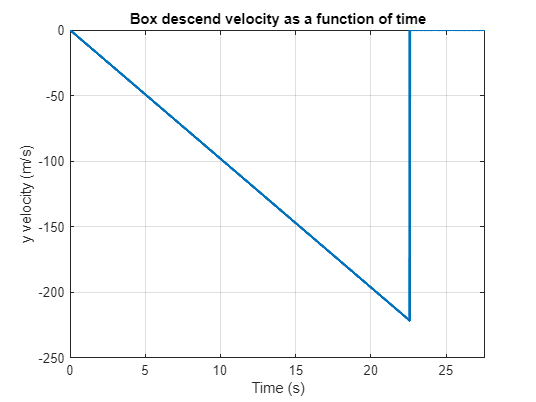


figure(3)
plot(t,vy, LineWidth=2) %plot the descend velocity of the box as a function of time
xlim([0,t(tg+1)+5])
xlabel 'Time (s)'
ylabel 'y velocity (m/s)'
title 'Box descend velocity as a function of time'
grid on

# Task 3: Including Air Resistance

Use the incomplete code below to solve task 3

%With air drag and lift force
%Note: x_with_air is a vector with information about x(t) for task 3
%(skydiver)

x_with_air(1) = x0; %Initial x position
y_with_air(1) = y0; %Initial y position

vx_with_air = v0(1); %Initial x velocity
vy_with_air = v0(2);  %Initial y velocity

y_parachute_open = FILL_IN_HERE; %Elevation when the parachute deploys

Unrecognized function or variable 'FILL_IN_HERE'.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

FILL_IN_HERE %Create your own loop, like show in task 2 to do numerical integration
%You will need to have multiple lines of code here.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

figure(4)
FILL_IN_HERE %plot the descend velocity of the skydiver as a function of time
xlabel 'Time (s)'
ylabel 'Descend velocity (m/s)'
title 'Skydiver descend velocity as a function of time'
grid on

figure(5)
FILL_IN_HERE %plot the trajector of the skydiver as a function of time
xlabel 'x position (m)'
ylabel 'y position (m)'
title 'Skydiver position with air drag or lift force'
grid on

figure(6)
FILL_IN_HERE %plot the elevation of the skydiver as a function of time
xlabel 'Time (s)'
ylabel 'y position (m)'
title 'Skydiver elevation as a function of time'
grid on